# **KINOVA Gen3 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

robot_name = 'kinovaGen3';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "EndEffector_Link"; 

Specify initial and desired end-effector poses. Use inverse kinematics to solve for the initial robot configuration given a desired pose.

orientation = axang2tform([1 0 0 pi/2])*axang2tform([0 1 0 pi/2]);

% Initial end-effector pose
taskInit = trvec2tform([[0.4 0 0.2]])*orientation;
% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.35 0.55 0.35])*orientation;
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

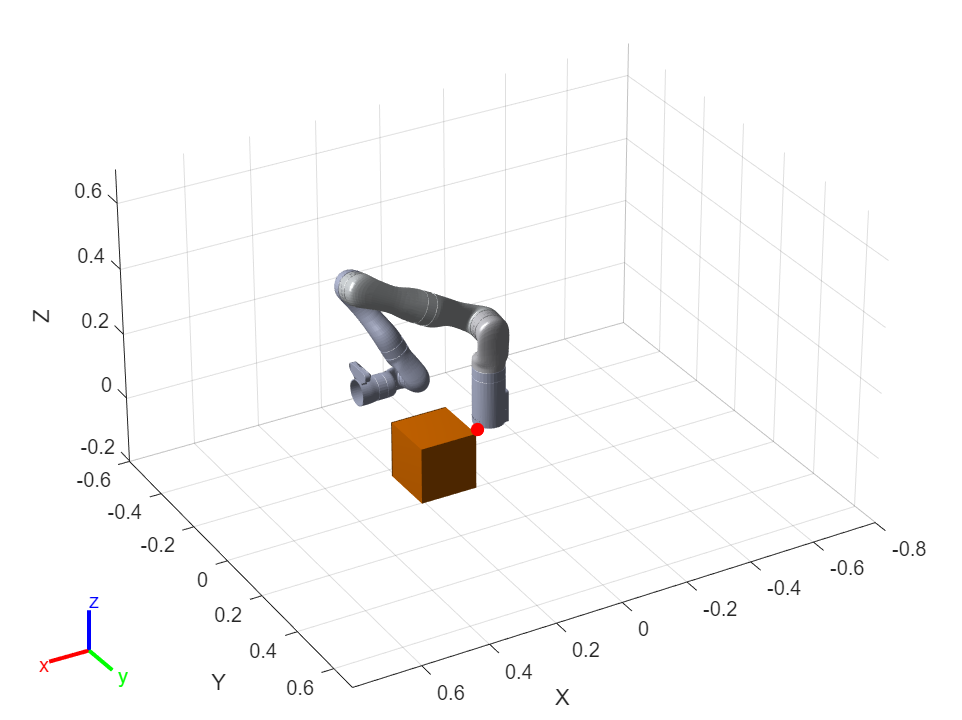

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

Elapsed time is 4.005932 seconds.


Qtheta = 232.0707

RAR = 2.5321

Elapsed time is 3.979308 seconds.


Qtheta = 218.4046

RAR = 2.5328

Elapsed time is 4.001814 seconds.


Qtheta = 182.1871

RAR = 2.5365

Elapsed time is 4.004068 seconds.


Qtheta = 167.2940

RAR = 2.5381

Elapsed time is 3.972122 seconds.


Qtheta = 149.0789

RAR = 2.5419

Elapsed time is 3.956177 seconds.


Qtheta = 124.2855

RAR = 2.5442

Elapsed time is 3.883108 seconds.


Qtheta = 108.0806

RAR = 2.5462

Elapsed time is 3.892285 seconds.


Qtheta = 94.1622

RAR = 2.5521

Elapsed time is 3.936885 seconds.


Qtheta = 88.7264

RAR = 2.5526

Elapsed time is 3.933851 seconds.


Qtheta = 73.7759

RAR = 2.5553

Elapsed time is 3.893893 seconds.


Qtheta = 66.5232

RAR = 2.5570

Elapsed time is 3.893825 seconds.


Qtheta = 58.1321

RAR = 2.5572

Elapsed time is 3.895321 seconds.


Qtheta = 53.6159

RAR = 2.5590

Elapsed time is 4.028734 seconds.


Qtheta = 36.0891

RAR = 2.5591

Elapsed time is 3.991124 seconds.


Qtheta = 29.2234

RAR = 2.5622

Elapsed time is 4.053003 seconds.


Qtheta = 27.3391

RAR = 2.5651

Elapsed time is 3.897813 seconds.


Qtheta = 22.2028

RAR = 2.5648

Elapsed time is 3.888764 seconds.


Qtheta = 18.6143

RAR = 2.5649

Elapsed time is 3.887649 seconds.


Qtheta = 18.1601

RAR = 2.5657

Elapsed time is 3.952975 seconds.


Qtheta = 13.2818

RAR = 2.5664

Elapsed time is 3.997387 seconds.


Qtheta = 10.4749

RAR = 2.5697

Elapsed time is 3.999207 seconds.


Qtheta = 7.2571

RAR = 2.5710

Elapsed time is 3.892010 seconds.


Qtheta = 6.5078

RAR = 2.5750

Elapsed time is 3.884013 seconds.


Qtheta = 6.6466

RAR = 2.5769

Elapsed time is 3.966336 seconds.


Qtheta = 6.5423

RAR = 2.5748

Elapsed time is 3.966965 seconds.


Qtheta = 6.1937

RAR = 2.5749

Elapsed time is 3.961882 seconds.


Qtheta = 5.8040

RAR = 2.5737

Elapsed time is 3.963801 seconds.


Qtheta = 6.0284

RAR = 2.5721

Elapsed time is 3.961248 seconds.


Qtheta = 5.3520

RAR = 2.5725

Elapsed time is 3.968873 seconds.


Qtheta = 5.4180

RAR = 2.5723

STOMP Finished.


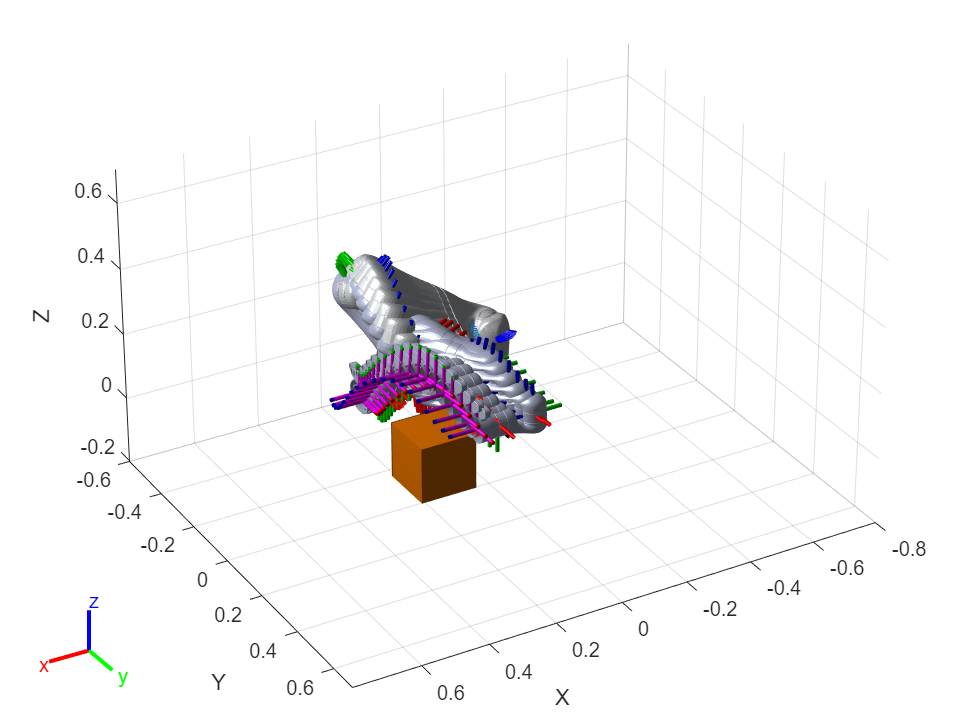

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.